## EXERCISE 3

A protein has an oscillatory behavior descripted by the following equation:

         where     a=0.25

## task 1. 

Plot the two terms to highlight fixed points ( 𝑑𝑝𝑑𝑡=0) in the diagram.

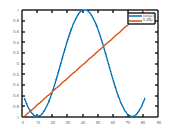

p = -4:0.1:4;                               % DOUBT: how was this value established?????
a = 0.25;
figure
plot(cos(p), 'DisplayName','cos(p)')        % DOUBT: wtf is the x-axis?
hold on
plot(a*p, 'DisplayName',[num2str(a) 'p'])
legend()

• linerar curve: production term

• cos(p): removal term

• fixed point: intersection of the two curves

## task 2.

Can you distinguish stable and unstable fixed points?

We want to distinguish between stable and unstable fixed points we have to look at the sign of the derivative before and after the points:

first fixed point:

- before: removal term higher than the production so the derivative is negative;

- after: removal term lower than the production term the derivative is positive

- So this is an **unstable **fixed point both arrows point away from the two curves.

second fixed point:

- before: the production is higher positive derivative;

- after: the removal is higher negative derivative. 

- So this is a **stable **fixed point because the arrows point towards the point.

third fixed point

- before: removal higher negative derivative;

- after: production higher positive derivative.

-  So this is an **unstable **fixed point.

## task 3.

What happens to the fixed points as you increase the value of a? 

Consider a=0.25, a=0.34, a=0.40

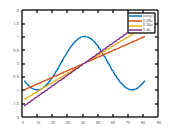

p = -4:0.1:4;
figure
plot(cos(p), 'DisplayName','cos(p)')
hold on
for a = [0.25,0.34,0.40]
plot(a*p, 'DisplayName',[num2str(a) 'p'])
end
legend()

As we increase a, the number of fixed points decreases.

• a=0.34: we have two fixed points (the first is tangent)

• a=0.4 we have only one fixed point

## EXERCISE 2

A circuit is described by the following dynamics equations:

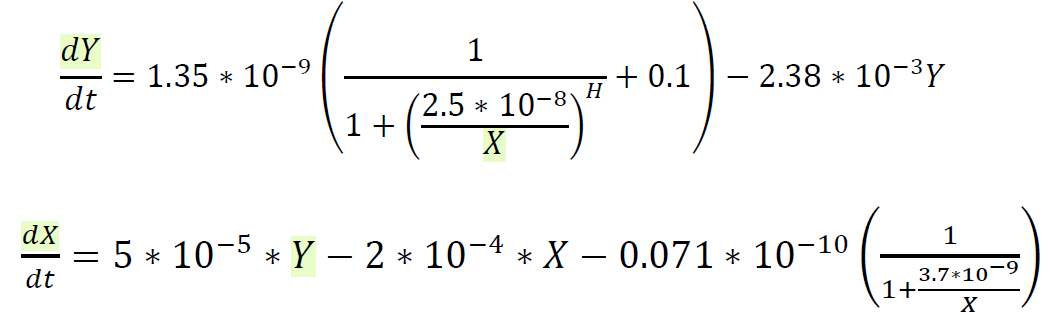

## task 1. 

Plot the nullclines (curves correspondent to null derivatives) considering H=1:

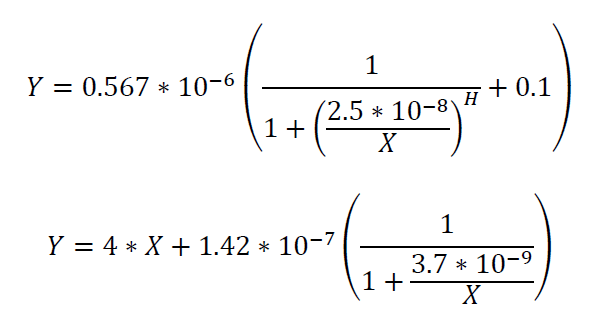

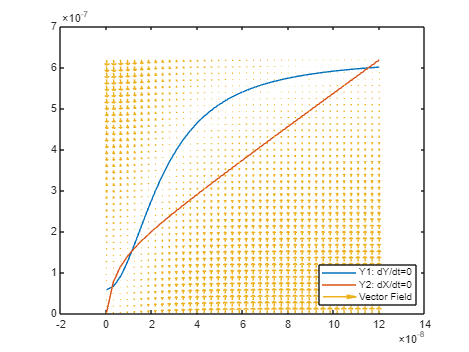

H = 2;
X = linspace(0,12*10^-8,40); %40 is the number of points            % For a better visualization, increase the number of points from 40 to 80 in task 2
                                                                    % DOUBT: how the hell do I even get to know which is the range of X of interest                                                                    
Y1 = (0.567*10^-6)*((1./(1+((2.5*10^-8)./X).^H))+0.1);
Y2 = (4*X)+((1.42*10^-7).*(1./(1+((3.7*10^-9)./X)))); 

figure
plot(X,Y1, 'DisplayName','Y1: dY/dt=0')
hold on
plot(X,Y2, 'DisplayName','Y2: dX/dt=0')

Ymesh = linspace(min([Y1 Y2]),max([Y1 Y2]),40);                     % DOUBT: what am I doing here, why am I considering min and max
[Xquiv, Yquiv] = meshgrid(X,Ymesh);

dX = (5*10^-5.*Yquiv)-(2*10^-4.*Xquiv)-(0.071*10^-10.*(1./(1+((3.7*10^-9)./Xquiv))));
dY = (1.35*10^-9.*((1./(1+((2.5*10^-8)./Xquiv).^H))+0.1))-(2.38*10^-3.*Yquiv);

quiver(Xquiv, Yquiv,dX,dY, 'DisplayName', 'Vector Field')           %DOUBT: how do I understand the stability of the fixed points with this function? 
legend('Location', 'se')                                                    % (I guess the first one that I provide so curve Y1 should be above, like the production in the rate plot)

We have just one fixed point: the arrows poin toward the point so this is a stable fixed point.

## task 2.

 What happens if H= 2?

Now we have 3 fixed points:

1. stable

2. unstable

3. stable

So this is a bistable system for H=2.

## EXERCISE 3

Consider the following example of mutual repression system:

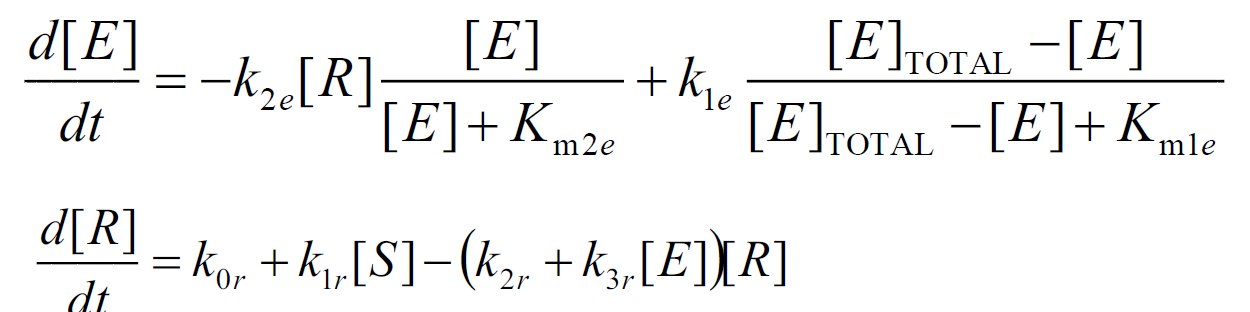

Plot the time course of R at different values of [S] (values: 2 6 12) 

and verify that initial conditions determine which steady state is reached.

Basically I need to apply the euler's method as seen in lab5 to be able to plot the curves given the differerential equation and the initial conditions of the curves (see in the code), I just need to do it on a multidimensional object as to plot multiple scenarios

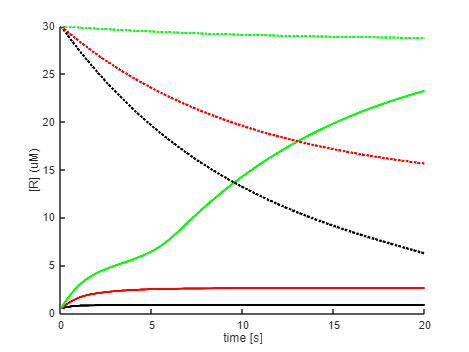

colors = 'krgbmc';
k0r = 0; k1r = 0.25; k2r= 0.1; k3r = 0.5;
k1e = 1; k2e = 0.2; Km1e = 0.05; Km2e = 0.05; Etot = 1;         %DOUBT: where the hell these come from?

% initial conditions of R
Rics = [0.5,30];                                                % needed for euler's
tests = length(Rics);

% initial condition of S
S = [2,6,12];
trials = length(S);

dt = 5e-3;
tlast = 20;
iterations = fix(tlast/dt);                                     % DOUBT: when using euler's method like this, should I fix or round?
time = dt*(0:iterations-1);

R_all = zeros(tests,trials,iterations);                         % 3D array:     rows=tests (1,2);     columns=trials (1,2,3) ;    z-axis/depth = iterations (1-3999) 
R_last = zeros(tests,trials);

figure
hold on

for iii=1:tests         % different initial conditions
    for ii=1:trials     % different values of S
        R = Rics(iii);  % initial condition
        E = 0.02;

        for i=1:iterations
            R_all(iii,ii,i) = R;
            dR = k0r + k1r*S(ii) - (k2r+k3r*E)*R;                % dR/dt
            dE = -k2e*R*E/(Km2e+E) + k1e*(Etot-E)/(Km1e+Etot-E); % dE/dt
            R = R+dR*dt;
            E = E+dE*dt;
        end

        R_last(iii) = R;                                    % DOUBT: what is this shit stored for? why do I care about the R at tlast=20 for S=2 and how it changes if Ri was 0.5 vs 30?

        %plot this specific xcombination for test and trial
        if(iii==1)
            plot(time,squeeze(R_all(iii,ii,:)), ...
                [colors(ii),'-'],'LineWidth',2.2)
        else
            plot(time,squeeze(R_all(iii,ii,:)), ...
                [colors(ii),':'],'LineWidth',2.2)
        end
    end
end                                                             

xlabel('time [s]')
ylabel('[R] (uM)')

set(gca, 'TickDir') % controls the appearence of the plot

  4×1 cell array

    {'in'  }
    {'out' }
    {'both'}
    {'none'}



We have concentrations of R for different initial conditions. Each color represent a different value of S.